## Example 2: Fitting EEG data

In this example we will load a prepared EEG dataset using EEGLAB.

**EEGLAB must be installed** and available in the MATLAB path; otherwise get it here from [eeglab.org](https://eeglab.org/others/How_to_download_EEGLAB.html).

### Loading the dataset

The altered example dataset contains a grand average of preprocessed EEG data for three channels (electrodes), with an ERN (error-related negativity) component.

eeglab('nogui');
% Load preprocessed EEG data (grand average)
EEG = pop_loadset('filename', 'eegERN.set', 'filepath', '');

pop_loadset(): loading file eegERN.set ...


EEG = eeg_checkset(EEG);

### Running the GMA with EEG data

For EEG data from EEGLAB, we can conveniently use `gmaFitEeg`, which reads all necessary data (e.g., the sample rate) from the EEG object. Since we want to fit a negative component, we will use the inverted data (thus, set `invData=true`).

We will search for the ERN component within the data points from 51 (0 ms) to 101 (100 ms) in the response-locked data of the FCz electrode.

In this example, we will also check the Cz and Fz electrodes, but only use the same starting point of 0 ms and search the window to the end of the data. We will also set the minimum correlation of the fitted PDF with the data to 0.9 in Fz; lower correlations will be flagged as unsuccessful fit.

% FCz electrode (channel 2)
gFCz = gmaFitEeg(EEG, 2, 51, 50, invData=true, logEnabled=false);

% Cz electrode (channel 3)
gCz = gmaFitEeg(EEG, 3, 51, invData=true, logEnabled=false);

% Fz electrode (channel 1)
gFz = gmaFitEeg(EEG, 1, 51, invData=true, logEnabled=false);
gFz.minCorr = 0.9;

### Plotting

**Electrode FCz:** visually a good match with good correlation and normalized root-mean-squared error (nRMSE) values and importantly the mode is in the range, we expected.

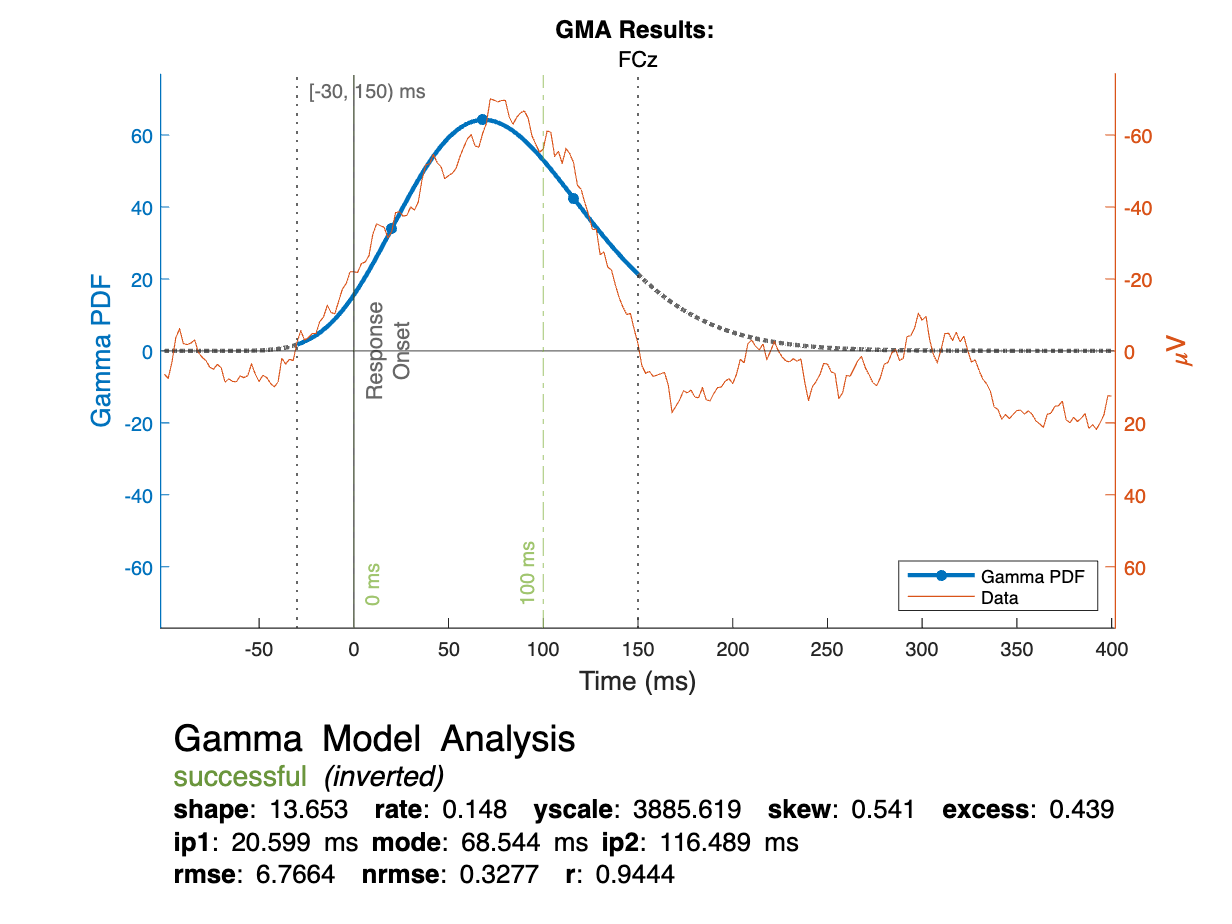

plotGmaResults(gFCz);
xl = xline(51, '-', {'Response', 'Onset'});
xl.LabelVerticalAlignment = 'middle';

**Electrode Cz:** quite similar to the fit on the FCz data 

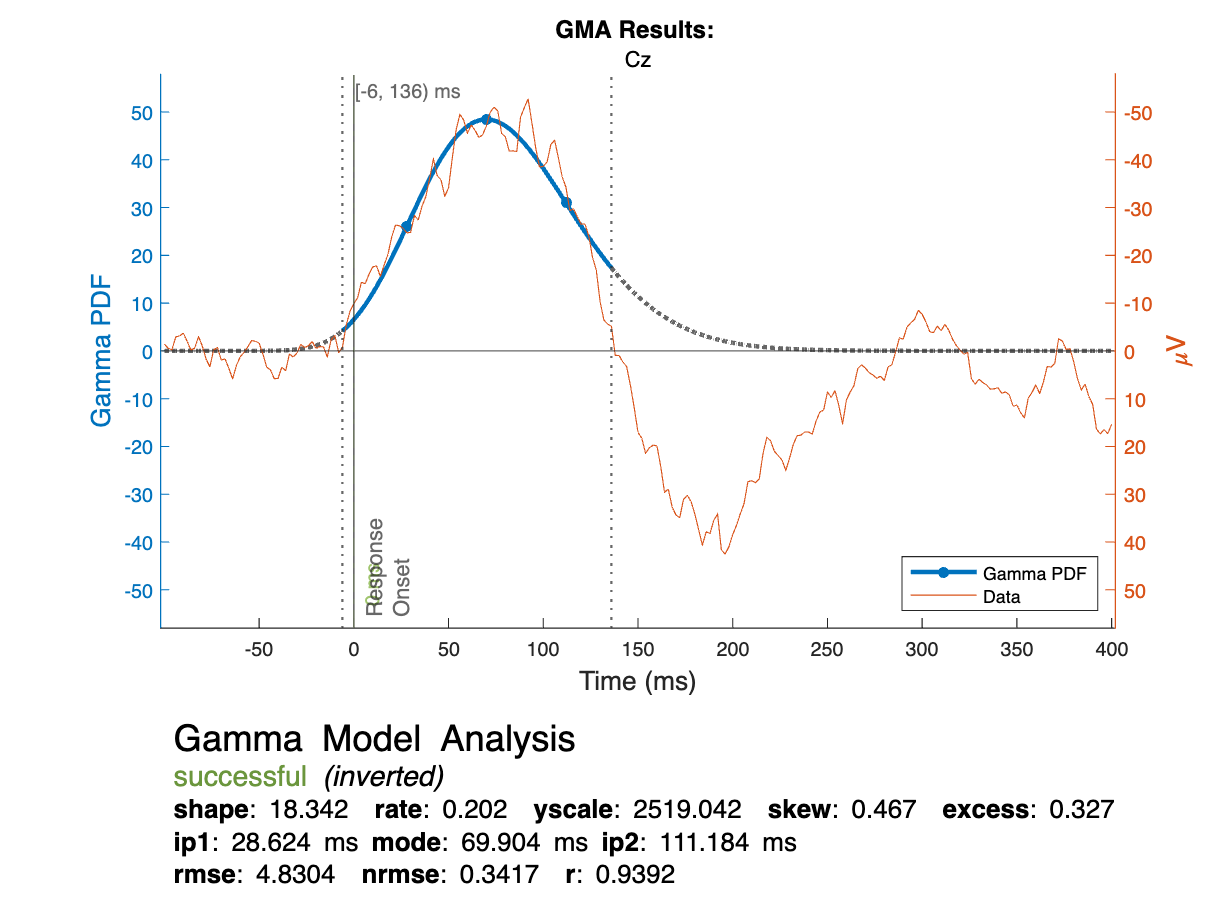

plotGmaResults(gCz);
xl = xline(51, '-', {'Response', 'Onset'});
xl.LabelVerticalAlignment = 'bottom';

**Electrode Fz:** in comparison to the FCz and Cz fits, there is no clear component here. Since the correlation is below our threshold of 0.9, the fit is flagged as unsuccessful.

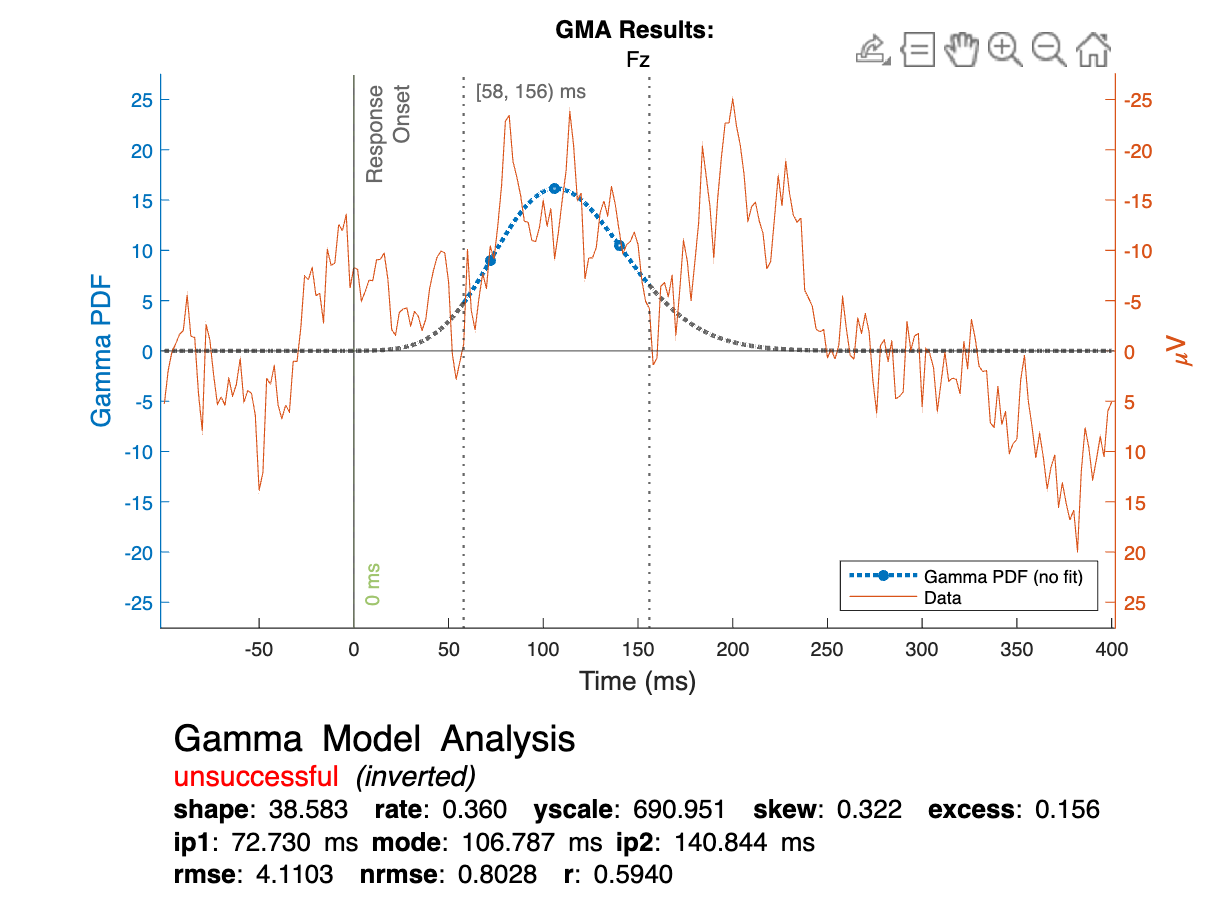

plotGmaResults(gFz);
xl = xline(51, '-', {'Response', 'Onset'});
xl.LabelVerticalAlignment = 'top';

### Extracting results

One benefit of the `GmaResults` class is that it encapsulates the original data and the achieved fit. When fitting EEG data, the meta data from EEGLAB (original file name, subject, session, ...) can also be retrieved from the instance. The object can be **saved to a mat-file** for later extraction of the results or to re-run the GMA with different settings.

For each `GmaResults` instance, common measures can be extracted a `struct` or as a `table`:

gFCz.asTable

ans = 1×23 table
    eegName    eegChLabel    eegRate      eegFile       eegPath    inverted     fit     win1    win2    seg1    seg2    shape      rate      yscale     ip1      mode      ip2       skew      excess      mse       rmse      nrmse        r   
    _______    __________    _______    ____________    _______    ________    _____    ____    ____    ____    ____    ______    _______</

Additional measures like the interquartile range, the median or the variance of the Gamma PDF can also be calculated using the `GmaResults` instance:

fprintf("IQR=%.3f", gFCz.iqr);

IQR=33.143

fprintf("median=%.3f", gFCz.median);

median=89.775

fprintf("var=%.3f", gFCz.var);

var=620.101